## Cambiar nombre de archivos en la PowerShell

% cd C:\Users\usuario\Desktop\Datos_Boya_Gando\files
% Dir|%{Rename-Item $_ -NewName ("BoyaGando_{0}.xml" -f $nr++)}

% cd C:\Users\usuario\Desktop\Datos_Boya_Gando\filesOptode
% Dir|%{Rename-Item $_ -NewName ("BoyaGando_{0}.xml" -f $nr++)}

## Coger los ficheros y extraer los datos y juntarlos

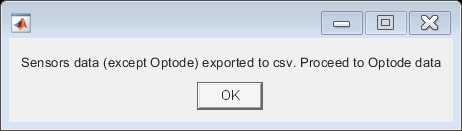

% Importa todos los archivos xml enviados por los sensores. A estos
% archivos primero hay que ponerles el mismo nombre.

% 1. Copiar los archivos que se quieren importar en una carpeta donde solo
% estén esos archivos.

% 2. Abrir la PowerShell:

% cd C:\Users\TESTER\OneDrive\Escritorio\Datos_Boya_Gando\files

% Dir|%{Rename-Item $_ -NewName ("BoyaGando_{0}.xml" -f $nr++)}

% A continuación, ya podemos importar los archivos y limpiarlos mediante el
% siguiente script.
%
% Antes, podemos importar uno de nuestros archivos. Veremos que MATLAB lo organiza
% en una tabla, así que hemos de seleccionar la celda donde se encuentra la
% información que nos interesa (los resultados, en nuestro caso, se encuentra en [6,6]).

% Seleccionamos esa celda, en Output type ponemos Column vectors y
% cambiamos el nombre de la primera columna a rawdata. Ponemos Import
% selection y Generate function para generar un archivo con una función que importe la
% celda que nos interesa de cada archivo, que es la de los resultados.

% Antes de guardar este archivo de la función, podemos cambiar el nombre de importfile al
% nombre que queramos, aunque es importante saber que este ya no podrá
% cambiarse posteriormente para evitar fallos. Por ejemplo, aquí lo hemos llamado
% VariosImportXML.

% Hay que guardar este archivo de la función y el presente script en la
% misma carpeta donde estamos trabajando y donde queremos que se cree el
% archivo CSV final.

% A continuación, el script importa cada uno de los archivos de la carpeta
% y crea el array rawdata para contenerlos.

clear
clc

listFiles = dir('C:\Users\usuario\Desktop\Datos_Boya_Gando\files\*.xml');
numFiles = numel(listFiles);

rawdata = [];

for i=0:(numFiles-1)

    myfilename=['C:\Users\usuario\Desktop\Datos_Boya_Gando\files\BoyaGando_',num2str(i),'.xml'];
    rawdata=[rawdata;GandoImportXML3(myfilename)];
    
    
    % Eliminar las tabulaciones al inicio de cada columna
    rawdata = table(replace(rawdata.Var1, sprintf("\t"), ""), replace(rawdata.Var2, sprintf("\t"), ""));
    
    % Elimina los caracteres @<, Z y <sos:resultValues> de todas las líneas.
    
    match = ["Z", "<sos:resultValues>", "<sos:template>", "<", "@<", "swe_bridge_"];
    rawdata = table(erase(rawdata.Var1, match), erase(rawdata.Var2, match));
    
    % Sustituye la T que separa la fecha de la hora por un espacio.
    
    rawdata = table(rawdata.Var1, strrep(rawdata.Var2,'T',' '));
    
end

% Cambiar el nombre de las variables
rawdata = renamevars(rawdata, ["Var1", "Var2"], ["Type", "Value"]);

% Crea archivo csv (si quieres)

question = "Rawdata table created. Generate csv file? y/n: ";
answer = input(question, "s");

if answer == "y"
    
    prompt = "File date? ";
    fileName = "C:\Users\usuario\Desktop\Datos_Boya_Gando\BoyaGando" + input(prompt, "s") + ".csv";
    writetable(rawdata, fileName, "Delimiter", "\t");
    msgbox("Sensors data (except Optode) exported to csv. Proceed to Optode data")
    
else
    
    msgbox("Rawdata was not exported. Proceed to Optode data")
    
end


% IMPORT OPTODE

listFiles2 = dir('C:\Users\usuario\Desktop\Datos_Boya_Gando\filesOptode\*.xml');
numFiles2 = numel(listFiles2);

rawOptode = [];

for k=0:(numFiles2-1)
    
    myfilename2=['C:\Users\usuario\Desktop\Datos_Boya_Gando\filesOptode\BoyaGando_',num2str(k),'.xml'];
    rawOptode = [rawOptode; importOptode(myfilename2)];
    
    % Elimina los caracteres @<, Z y <sos:resultValues> de todas las líneas de
    % rawdata.
    rawOptode.dateOpt = erase(rawOptode.dateOpt, match);
    
    % Sustituye la T que separa la fecha de la hora por un espacio.
    rawOptode.dateOpt = strrep(rawOptode.dateOpt,'T',' ');
    
end

% Separa los datos en base al delimiter #
dateSplit = split(rawOptode.dateOpt, "#");

Dot indexing is not supported for variables of this type.


% Crea una tabla con las medidas de oxígeno, % de saturación y temperatura
% junto con la fecha de medición
rawOptode = table(rawOptode.VarName4, rawOptode.VarName5, rawOptode.VarName6, dateSplit(:,1));

% Introduce el formato de fecha
rawOptode.Var4 = datetime(rawOptode.Var4, "InputFormat", "uuuu-MM-dd HH:mm:ss");

% Ordena las variables de la tabla
rawOptode = movevars(rawOptode, "Var4", "Before", "Var1");

% Modifica el nombre de las variables
rawOptode = renamevars(rawOptode, ["Var4", "Var1", "Var2", "Var3"], ["Date", "O2", "Saturation", "Temp"]);

% Crea un archivo CSV con los datos ya organizados (si quieres)

question2 = "Optode table created. Generate csv file? y/n: ";
answer2 = input(question2, "s");

if answer2 == "y"
    
    prompt2 = "File date? ";
    fileName2 = "C:\Users\usuario\Desktop\Datos_Boya_Gando\BoyaGando" + input(prompt2, "s") + "Opt.csv";
    writetable(rawOptode, fileName2, "Delimiter", "\t");
    msgbox("Optode data saved to csv. End of script.")
    
else
    
    msgbox("End of script without exporting Optode")
    
end